# Całkowe przekształcenie Fouriera

#### Mateusz Wójcik, 14.11.2024

Całkowe przekształcenie Fouriera jest jednym z fundamentalnych narzędzi matematycznych w analizie sygnałów, fizyce, inżynierii i wielu innych dziedzinach nauki. Umożliwia ono przejście między reprezentacją sygnału w dziedzinie czasu, a jego reprezentacją w dziedzinie częstotliwości. W trakcie tych zajęć laboratoryjnych celem jest zapoznanie się z podstawowymi zasadami używania oraz analizowania wyników całkowego przekształcenia Fouriera. Dodatkowo poruszono również tematy modulacji i "okienkowania". 

clear all; close all;

syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;

BND_t = [-10/f0 10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];

BND_w = [-3*w0 3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

x = sin(w0*t);
X_FT = fourier(x);

## Zadanie 1

Pierwsze zadanie polegało na wykorzystaniu podanego kodu w celu narysowania wykresów dla sygnału sinusoidalnego i jego transformaty Laplace'a

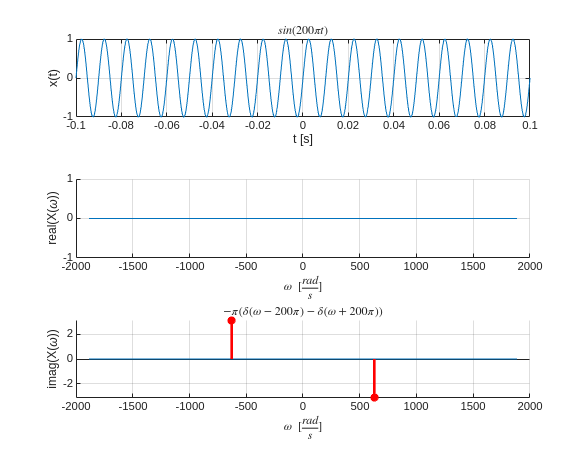

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(x, BND_t); 
title("$sin(200 \pi t)$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)');
xlabel('t [s]');
grid on


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
fplot(real(X_FT), BND_w); hold on; grid on;
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_FT), BND_w); 
title("$-\pi( \delta(\omega - 200\pi) - \delta(\omega + 200\pi))$",Interpreter="latex", FontWeight="bold")
v_num = subs(imag(X_FT), w, w_SMP);
grid on
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off

## Zadanie 2

Podczas wykonywania tego ćwiczenia należy zapoznać się w praktyce z transforamtami Fouriera różnych podstawowych funkcji takich jak cosinus, funkcja skokowa, funkcja stała, puls prostokątny czy puls trójkątny. Wszystkie wyniki przedstawiono na stosownie opisanych wykresach.

Każdą sekcje rozpoczęto od zdefiniowania funkcji  i wyznaczenia jej transformaty Fouriera. Następny, krokiem jest wykreślenie wykresów. Te kroki zastosowano dla wszystkich sygnałów:

- 
$$x(t)=cos(\omega_0t)$$


x_cos = cos(w0*t)

$$x\_cos = \cos\left(200\,\pi \,t\right)$$

X_cos = fourier(x_cos)

$$X\_cos = \pi \,\left(\delta (w-200\,\pi )+\delta (w+200\,\pi )\right)$$

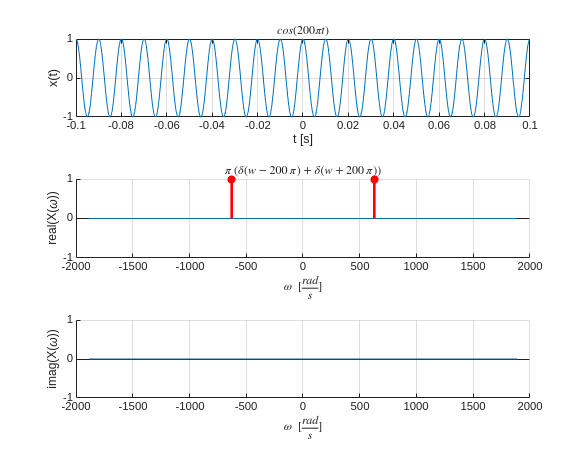

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(x_cos, BND_t); 
title("$cos(200 \pi t)$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]');
grid on

subplot(3,1,2); 
ylabel('real(X(\omega))'); 
hold on
fplot(real(X_cos), BND_w);
grid on;
title("$$\pi \,{\left({\delta }\left(w-200\,\pi \right)+{\delta }\left(w+200\,\pi \right)\right)}$$",Interpreter="latex", FontWeight="bold")
v_num = subs(real(X_cos), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
axis([-2000, 2000 -1 1])
hold off

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_cos), BND_w); 
v_num = subs(imag(X_cos), w, w_SMP);
grid on
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off

2. $x(t) = 10$

x_const = sym(10)

$$x\_const = 10$$

X_const = fourier(x_const)

$$X\_const = 20\,\pi \,\delta (w)$$

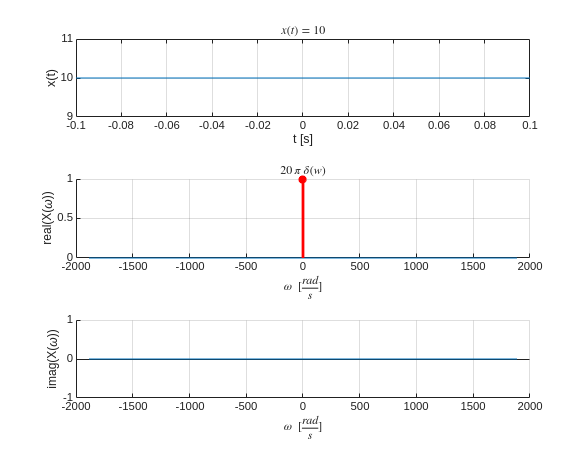

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(x_const, BND_t); 
title("$x(t) = 10$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]');
grid on

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
title("$20\,\pi \,{\delta }\left(w\right)$",Interpreter="latex", FontWeight="bold")
fplot(real(X_const), BND_w);
grid on;
v_num = subs(real(X_const), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_const), BND_w);
v_num = subs(imag(X_const), w, w_SMP);
grid on
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off

3. $x(t)=1(t)$

x_step = heaviside(t)

$$x\_step = \mathrm{heaviside}\left(t\right)$$

X_step = fourier(x_step)

$$X\_step = \pi \,\delta (w)-\frac{\mathrm{i}}{w}$$

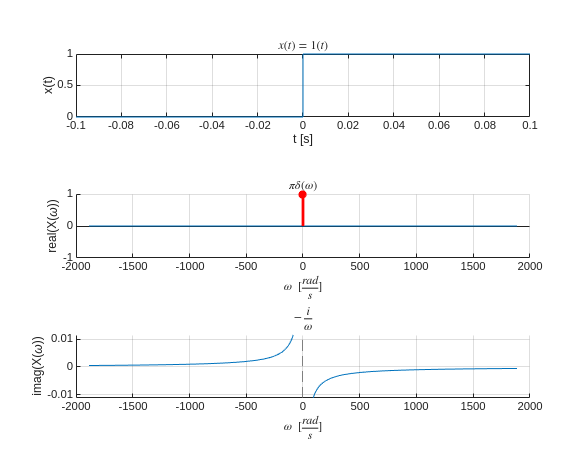

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(x_step, BND_t); 
title("$x(t) = 1(t)$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]');
grid on

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
fplot(real(X_step), BND_w);
grid on;
title("$\pi \delta(\omega)$", Interpreter="latex")
v_num = subs(real(X_step + 1i/w), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
axis([-2000 2000 -1 1])

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_step), BND_w);
title("$ -\frac{i}{\omega}$",Interpreter="latex", FontWeight="bold")
grid on
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off

4. $\[
f(t) = \begin{cases} 
      1 & \text{dla } \frac{-T_0}{2} \leq t \leq \frac{T_0}{2}  \\
      0 & \text{dla } \frac{-T_0}{2} > t  \land t > \frac{T_0}{2}  
   \end{cases}
\]$

x_rect_pulse = rectangularPulse(-1/(f0), 1/(f0), t)

$$x\_rect\_pulse = \mathrm{rectangularPulse}\left(-\frac{1}{100},\frac{1}{100},t\right)$$

X_rect_pulse = simplify(fourier(x_rect_pulse))

$$X\_rect\_pulse = \frac{2\,\sin\left(\frac{w}{100}\right)}{w}$$

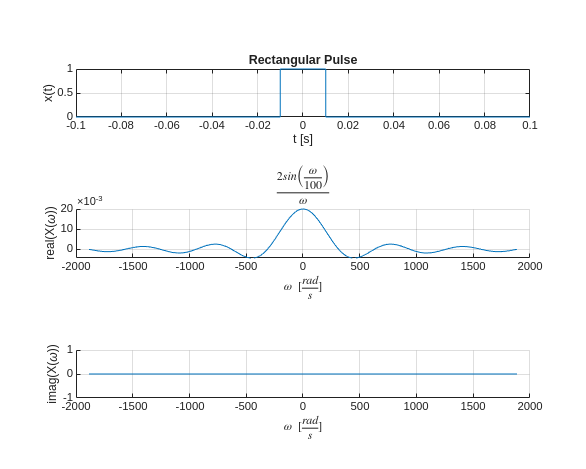

figure(Position=[100 100 1000 800])
subplot(3,1,1); 
fplot(x_rect_pulse, BND_t); 
title("Rectangular Pulse", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]');
grid on

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
fplot(real(X_rect_pulse), BND_w);
grid on;
title("$\frac{2 sin \left( \frac{\omega}{100} \right)}{\omega}$", Interpreter="latex")
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_rect_pulse), BND_w);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on

5. $\[
f(t) = \begin{cases} 
      \frac{2x + T_0}{T_0}   & \text{dla } \frac{-T_0}{2} \leq t < 0   \\
      \frac{T_0-2x}{T_0}   & \text{dla } 0 \leq t \leq 0 \frac{T_0}{2}  \\

      0 & \text{dla } \frac{-T_0}{2} > t  \land t > \frac{T_0}{2}  
   \end{cases}
\]$

x_triangle_pulse = triangularPulse(-1/f0,0, 1/f0,t)

$$x\_triangle\_pulse = \mathrm{triangularPulse}\left(-\frac{1}{100},0,\frac{1}{100},t\right)$$

X_triangle_pulse = fourier(x_triangle_pulse)

$$X\_triangle\_pulse = -\frac{100\,{\mathrm{e}}^{-\frac{w\,\mathrm{i}}{100}}\,{\left({\mathrm{e}}^{\frac{w\,\mathrm{i}}{100}}-1\right)}^{2}}{w^{2}}$$

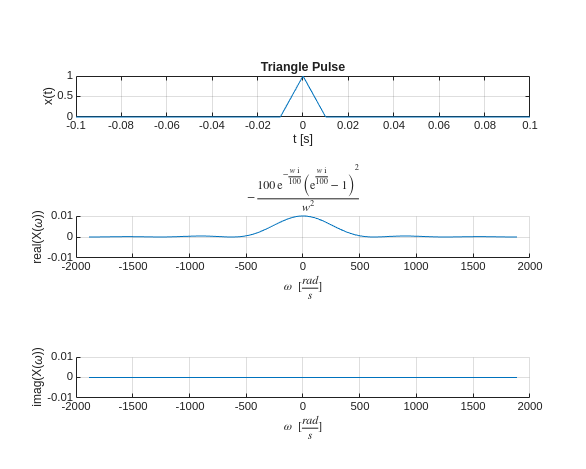


figure(Position=[100 100 1000 800])
subplot(3,1,1); 
fplot(x_triangle_pulse, BND_t); 
title("Triangle Pulse", FontWeight="bold")
ylabel('x(t)'); 
grid on
xlabel('t [s]');

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
fplot(real(X_triangle_pulse), BND_w);
grid on;
title("$-\frac{100\,{\mathrm{e}}^{-\frac{w\,\mathrm{i}}{100}} \,{{\left({\mathrm{e}}^{\frac{w\,\mathrm{i}}{100}} -1\right)}}^2 }{w^2 }$", Interpreter="latex")
axis([-2000 2000 -0.01 0.01])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_triangle_pulse), BND_w);
% title("$ -\frac{i}{\omega}$",Interpreter="latex", FontWeight="bold")
axis([-2000 2000 -0.01 0.01])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on

## Zadanie domowe 1

W celu wykonania tego polecenia należało stworzyć wykresy gęstości widmowej amplitudy oraz fazy dla funkcji cos i sin. Wyniki przedstawiono poniżej:

#### 1.$sin(\omega_0 t)$

x_sin = sin(w0 * t)

$$x\_sin = \sin\left(200\,\pi \,t\right)$$

X_sin = fourier(x_sin)

$$X\_sin = -\pi \,\left(\delta (w-200\,\pi )-\delta (w+200\,\pi )\right)\,\mathrm{i}$$

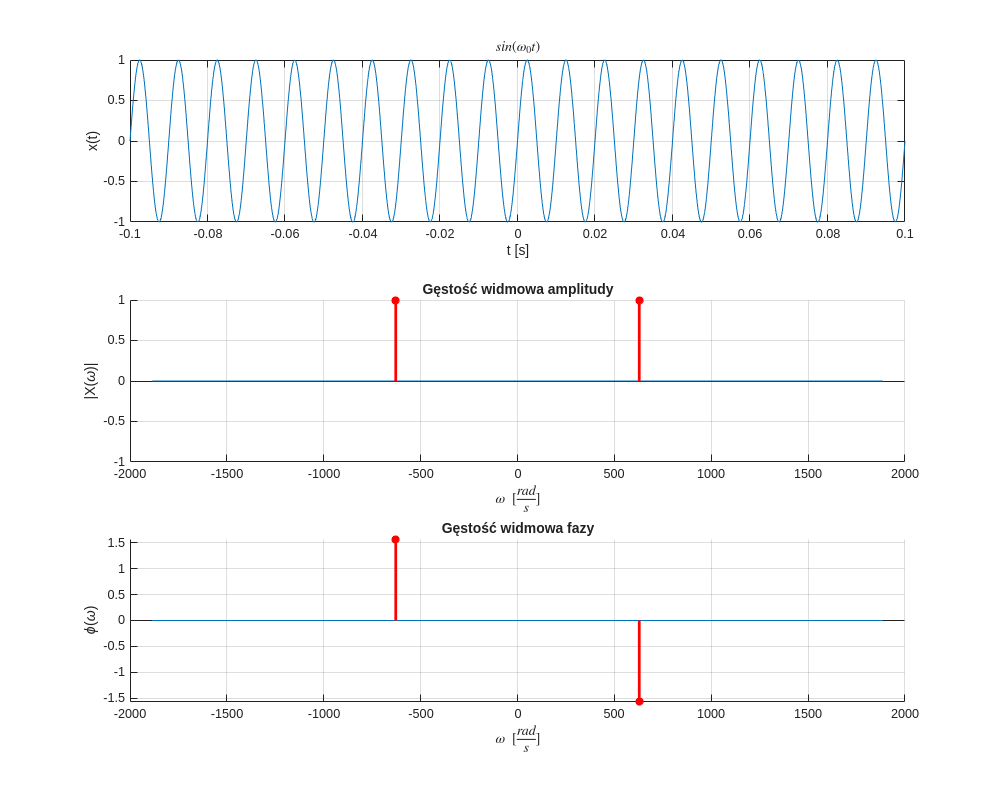


figure(Position=[100 100 1000 800])
subplot(3,1,1); 
fplot(x_sin, BND_t); 
title("$sin(\omega_0 t)$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]')
grid on

subplot(3,1,2); ylabel('|X(\omega)|'); hold on
fplot(abs(X_sin), BND_w);
grid on;
title("Gęstość widmowa amplitudy")
axis([-2000 2000 -0.01 0.01])
v_num = subs(abs(X_sin), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
axis([-2000 2000 -1 1])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

subplot(3,1,3); 
ylabel('\phi(\omega)');
hold on
fplot(angle(X_sin), BND_w);
title("Gęstość widmowa fazy")

v_num = subs(angle(X_sin), w, w_SMP);
n = find( abs(v_num) == pi/2); % plot dirac (inf)
stem(w_SMP(n),v_num(n),'r*', 'LineWidth', 2);
axis([-2000 2000 -pi/2 pi/2])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on
hold off

#### 2.$cos(\omega_0 t)$

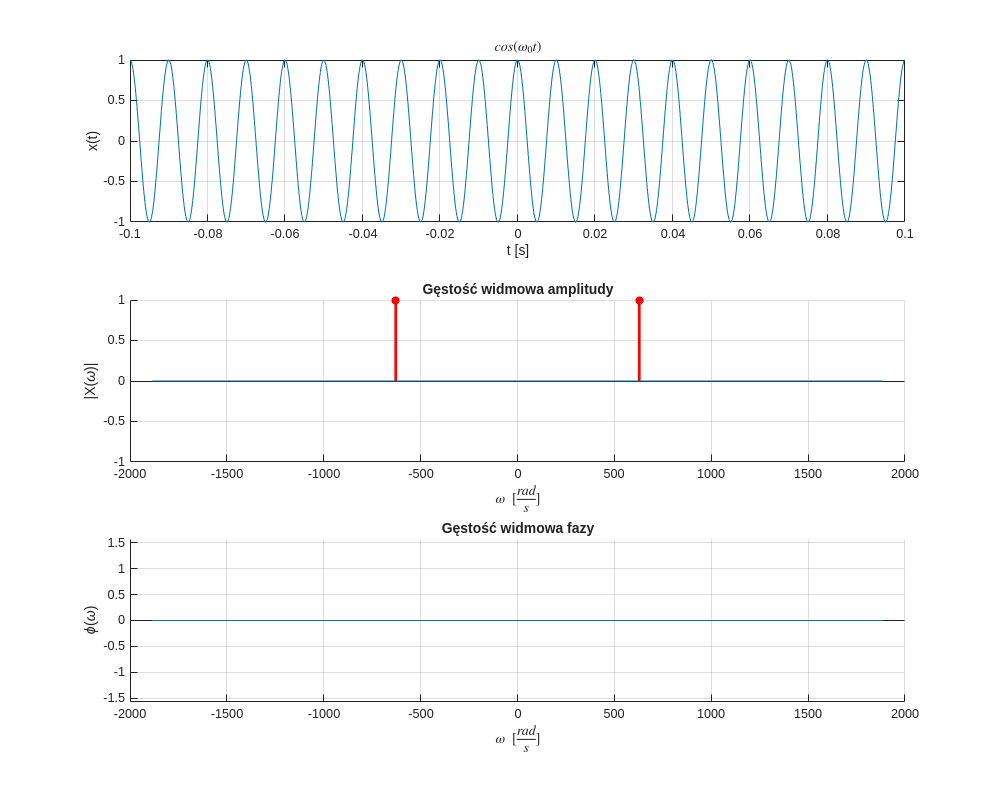

figure(Position=[100 100 1000 800])
subplot(3,1,1); 
fplot(x_cos, BND_t); 
title("$cos(\omega_0 t)$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]')
grid on

subplot(3,1,2); ylabel('|X(\omega)|'); hold on
fplot(abs(X_cos), BND_w);
grid on;
title("Gęstość widmowa amplitudy")
axis([-2000 2000 -0.01 0.01])
v_num = subs(abs(X_cos), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
axis([-2000 2000 -1 1])

subplot(3,1,3);
ylabel('\phi(\omega)');
hold on
fplot(angle(X_cos), BND_w);
title("Gęstość widmowa fazy")
v_num = subs(angle(X_cos), w, w_SMP);
n = find( abs(v_num) == pi/2); % plot dirac (inf)
stem(w_SMP(n),v_num(n),'r*', 'LineWidth', 2);
axis([-2000 2000 -pi/2 pi/2])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on
hold off

Porównując wykresy rzuca się w oczy, że gęstość widmowa amplitudy jest dla obu funkcji taka sama. Nie jest to nic dziwnego, ponieważ obie funkcje posiadają taką samą pulsację $\omega_0$. Róznica pojawiła się natomiast przy porównaniu wykresów przedstawiających gęstość widmową fazy. Dla funkcji $cos(\omega_0 t)$ nie ma żadnych punktów, natomiast dla funkcji $sin(\omega_0 t)$ pojawia się przesunięcie fazowe o kąt $\pi/2$. Można zatem zauważyć, że jest to przesunięcie jakie z definicji występuje pomiędzy funkcjami sin i cos.

## Zadanie 3

W tym ćwiczeniu głównym celem jest zapoznanie się z tematem modulacji sygnału. Modulacja sygnału to technika, która polega na zmianie parametrów fali nośnej w celu przenoszenia informacji. Najpopularniejsze typy modulacji to: Modulacja Amplitudy(AM), Częstotliwości (FM) i Fazy (PM). 

Modulacjie można spotkać na codzień, w aplikacjach telekomunikacyjnych, które pozwalają na przesyłanie danych na duże odległości przy zachowaniu odpowiednio wysokiej jakości sygnału. Modulacje można również spotkać w radiu, telewizji czy systemach satelitarnych. Można byłoby sądzić, że radio i telewizja są już przestarzałe i modulacja staje się niepotrzebna, otóż nic bardziej mylnego. Modulacja jest również wszechobecna w systemach bezprzewodowych sieci Wi-FI, czy w komunikacji Bluetooth, z których tak chętnie ludzkość korzystać. Oprócz tego wiele aplikacji Internetu Rzeczy bazuje komunikację między jednostkami, używając technik modulacji, do przesyłu danych na warstwie fizycznej.

m = 0.5;
scale = 10;
y = (1 + m*sin(w0/scale*t)) * cos(w0*t)

$$y = \cos\left(200\,\pi \,t\right)\,\left(\frac{\sin\left(20\,\pi \,t\right)}{2}+1\right)$$

Y = fourier(y)

$$Y = \pi \,\left(\delta (w-200\,\pi )+\delta (w+200\,\pi )\right)+\frac{\pi \,\left(\delta (w-180\,\pi )-\delta (w+180\,\pi )\right)\,\mathrm{i}}{4}-\frac{\pi \,\left(\delta (w-220\,\pi )-\delta (w+220\,\pi )\right)\,\mathrm{i}}{4}$$

Tworzenie wykresu przedstawiającego modulowaną funkcję:

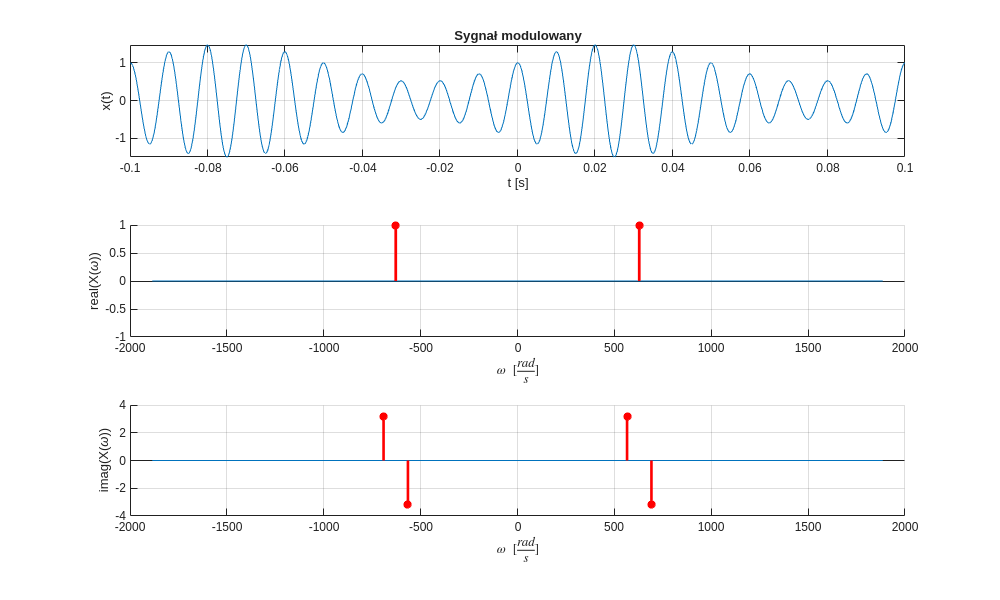

figure(Position=[100 100 1000 600])
subplot(3,1,1); 
fplot(y, BND_t); 
title("Sygnał modulowany", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]')
grid on

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
fplot(real(Y), BND_w);
grid on;
v_num = subs(real(Y), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
axis([-2000, 2000 -1 1])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(Y), BND_w);
% title("$ -\frac{i}{\omega}$",Interpreter="latex", FontWeight="bold")
v_num = subs(imag(Y), w, w_SMP);
grid on
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off

## Zadanie domowe 2

Przedstawiono poniżej wyniki obliczania mocy dla funkcji nośnej - sygnału $cos(\omega_0 t)$ oraz sygnału modulowanego. 

power_cos = f0 * int(x_cos^2, [-1/(f0*2), 1/(f0*2)])

$$power\_cos = \frac{1}{2}$$

power_modulated = f0/10 * int(y^2, [-10/(f0*2), 10/(f0*2)])

$$power\_modulated = \frac{9}{16}$$

Jak łatwo zauważyc sygnały te różnią się od siebie. Kluczowym parametrem w tej różnicy stanowi parametr m - głębokość modulacji. Otóż zależność między mocą sygnału nośnego, a sygnału zmodulowanego przedstawia zależność:


$$P_{mod} = P_{nos}(1 + \frac{m^2}{2})$$


## Zadanie 4

To polecenie skupiło się na przedstawieniu wpływu "okienkowania" na otrzymywany sygnał. "Okienkowanie" jest bardzo pożyteczne w celu dokonywania analizy wybranego fragmentu z dłuższego sygnału. Aby jednak dawało określone rezultaty, trzeba dobrać odpowiednią funkcję okna. Istnieje wiele różnych funkcji, takich jak okno Hanninga, Hamminga, Blackmanna, ale również "okienkowanie" pulsem prostokątny, trójkątnym, czy krzywą Gaussa. W tym ćwiczeniu przedstawiono wygląd transformat po zastosowaniu trzech ostatnich funkcji okna.

Całość rozpoczęto od zdefiniowania odpowiednich funkcji i transformat. 

rect_window = rectangularPulse(-6.5/(2*f0), 6.5/(2*f0), t);
triang_window = triangularPulse(-6.5/(2*f0),0, 6.5/(2*f0), t);

c = 6.5/(4*f0);
gaus_window = exp(- (t^2)/(2*c^2));

signal = cos(w0*t);
signal_rect = signal * rect_window;
signal_triang = signal * triang_window;
signal_gaus = signal * gaus_window;

rect_FT = fourier(signal_rect);
triang_FT = fourier(signal_triang);
gauss_FT = fourier(signal_gaus);

Następnie przystąpiono do utworzenia odpowiednich wykresów dla wszystkich sygnałów:

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(x_cos, BND_t); 
title("$cos(200 \pi t)$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]')
grid on

subplot(3,1,2); 
ylabel('real(X(\omega))'); 
hold on
fplot(real(X_cos), BND_w);
grid on;
title("$$\pi \,{\left({\delta }\left(w-200\,\pi \right)+{\delta }\left(w+200\,\pi \right)\right)}$$",Interpreter="latex", FontWeight="bold")
v_num = subs(real(X_cos), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
axis([-2000, 2000 -1 1])
hold off

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(X_cos), BND_w); 
v_num = subs(imag(X_cos), w, w_SMP);
grid on
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
hold off

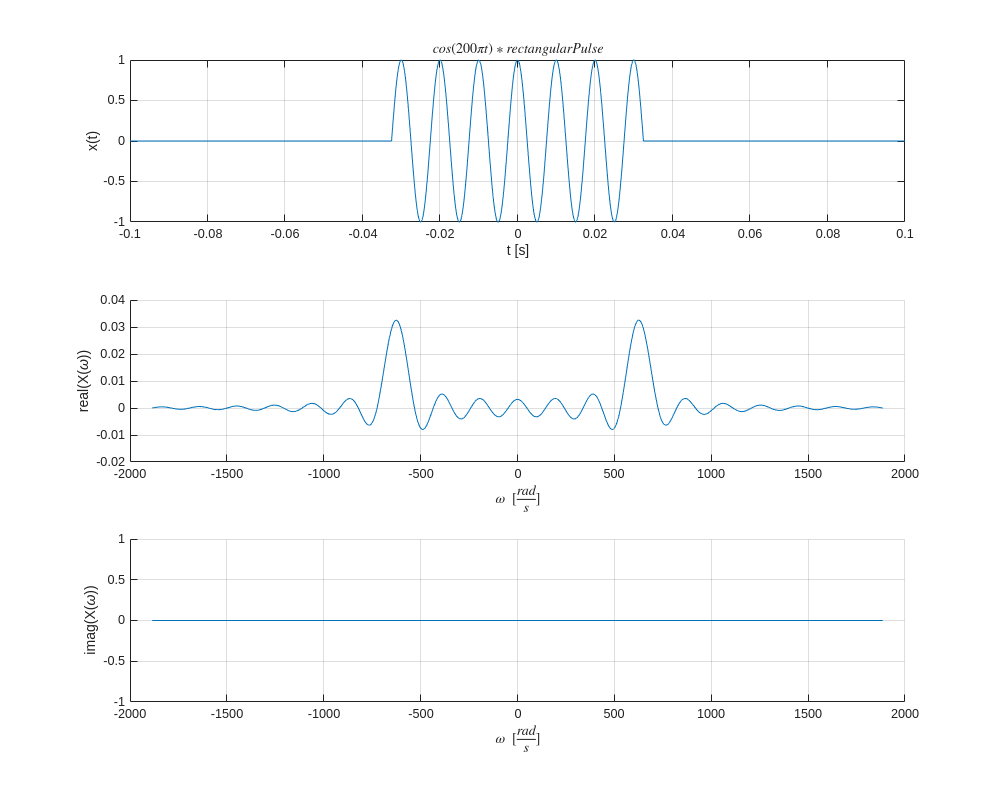

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(signal_rect, BND_t); 
title("$cos(200 \pi t) * rectangularPulse$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]')
grid on

subplot(3,1,2); 
ylabel('real(X(\omega))'); 
hold on
fplot(real(rect_FT), BND_w);
grid on;
axis([-2000 2000 -0.02 0.04])
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(rect_FT), BND_w);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on

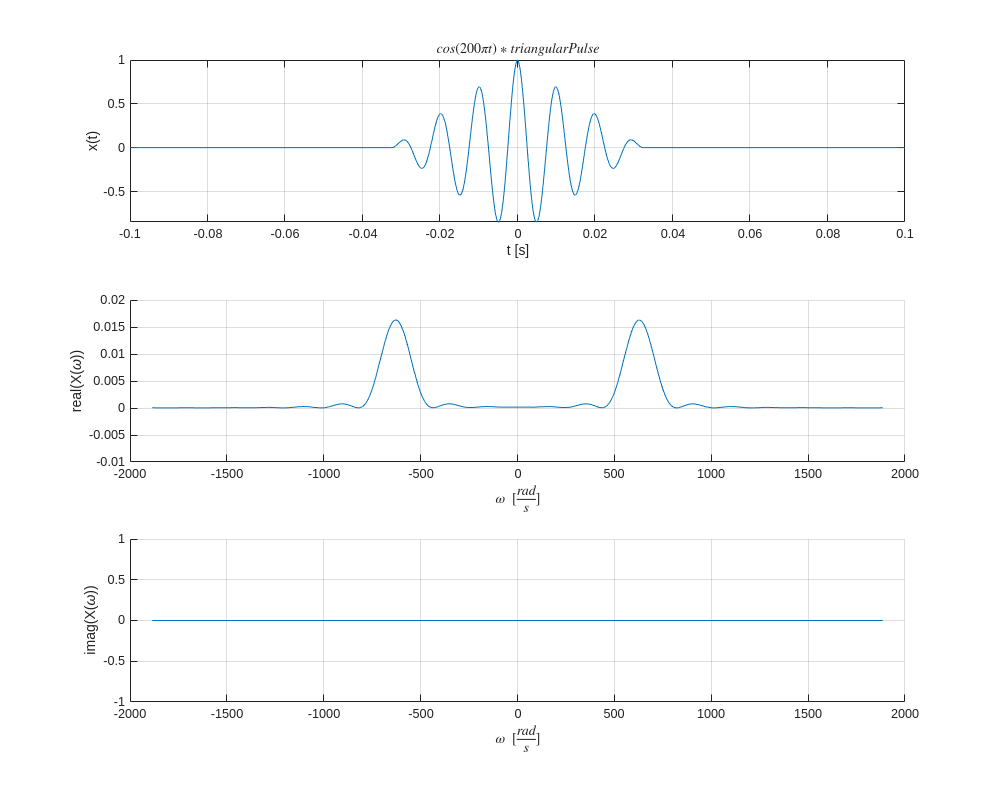

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(signal_triang, BND_t); 
title("$cos(200 \pi t) * triangularPulse$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel('t [s]')
grid on

subplot(3,1,2); 
ylabel('real(X(\omega))'); 
hold on
fplot(real(triang_FT), BND_w);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on;
axis([-2000 2000 -0.01 0.02])


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(triang_FT), BND_w);
grid on
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

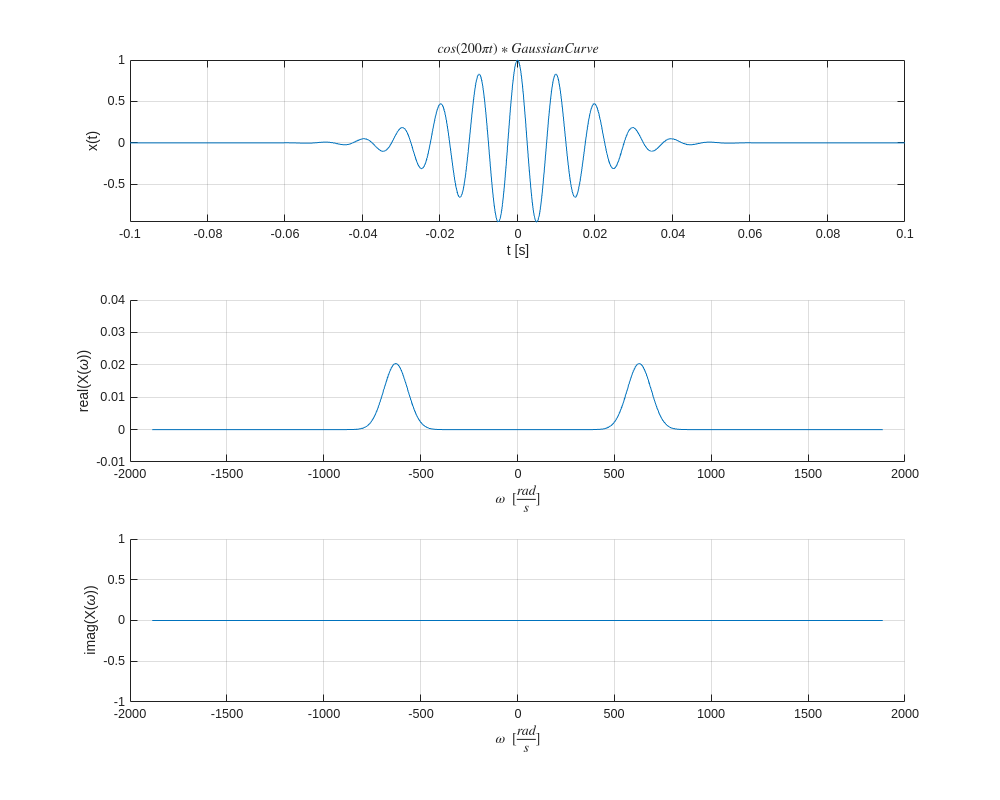

figure(Position=[100 100 1000 800])

subplot(3,1,1); 
fplot(signal_gaus, BND_t); 
title("$cos(200 \pi t) * Gaussian Curve$",Interpreter="latex", FontWeight="bold")
ylabel('x(t)'); 
xlabel("t [s]")
grid on

subplot(3,1,2); 
ylabel('real(X(\omega))'); 
hold on
fplot(real(gauss_FT), BND_w);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on;
axis([-2000 2000 -0.01 0.04])


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
fplot(imag(gauss_FT), BND_w);
grid on
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")

## Zadanie domowe 3

W ostatnim poleceniu celem było przeanalizowanie gęstości widmowej amplitudy dla wcześniej przedstawionych sposobów "okienkowania" sygnału. Zbiorcze wyniki przedstawiono poniżej na wykresie:

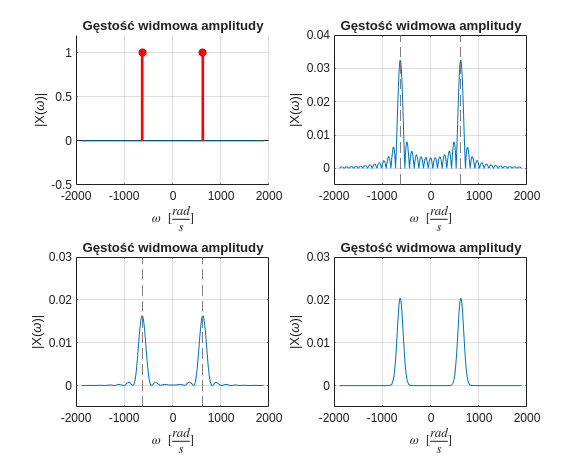

figure(Position =[100 100 1000 800])
subplot(2,2,1);
ylabel('|X(\omega)|'); hold on
fplot(abs(X_cos), BND_w);
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on;
title("Gęstość widmowa amplitudy")
axis([-2000 2000 -0.01 0.01])
v_num = subs(abs(X_cos), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
axis([-2000 2000 -0.5 1.2])
hold off

subplot(2,2,2)

fplot(abs(rect_FT), BND_w);
ylabel('|X(\omega)|'); 
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on;
title("Gęstość widmowa amplitudy")
axis([-2000 2000 -0.005 0.04])

subplot(2,2,3)

fplot(abs(triang_FT), BND_w);
ylabel('|X(\omega)|');
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on;
title("Gęstość widmowa amplitudy")
axis([-2000 2000 -0.005 0.03])

subplot(2,2,4)

fplot(abs(gauss_FT), BND_w);
ylabel('|X(\omega)|'); 
xlabel("$\omega \ [\frac{rad}{s}]$", Interpreter = "latex")
grid on;
title("Gęstość widmowa amplitudy")
axis([-2000 2000 -0.005 0.03])

Na podstawie analizy ostatnich dwóch ćwiczeń można stwierdzić, że pewne funkcje lepiej działają jako funkcje okna. Dobrym tego przykładem jest krzywa Gaussa, która nie wprowadza dodatkowych zakłóceń w gęstości widmowej amplitudy, w przeciwieństwie do takich funkcji jak np. puls prostokątny. Widać też zależność, że im gładsza jest funkcja okna tym mniejsze zakłócenia wprowadza. W praktyce jednak wybór odpowiedniej funkcji zależy od danej aplikacji, w której chcemy jej użyć, ponieważ ogromna ilość i różnie mogą reagować na sygnał wejściowy i rozciąganie ich na określoną długość próbki.

# Wnioski

Na laboratorium zapoznano się z kolejnymi elementami wprowadzającymi do przetwarzania sygnałów. Tym razem zajęto się całkowym przekształceniem Fouriera i zdobyto doświadczenie w odtwarzaniu i analizowaniu wykresów podstawowych funkcji. Oprócz tego na zajęciach poruszono temat modulacji, fundamentalnego sposobu przesyłu informacji przez różne media transmisyjne, bez którego ciężko byłoby wspominać o nowych standardach telekomunikacji. Zajęcia końzyły się ćwiczeniami dotyczącymi okienkowania, które pozwala nam na przeprowadzanie badania szczególnych okresów sygnału, który posiadamy oraz eliminowania negatywnych skutków generowanych przez warunki brzegowe.